# Figure 2 - Illustrate the main data sets

To measure lip and tongue fluorescence we needed to remove any reflected light from the light source.  These were always below 475nm, so added a 475 nm long pass to the system.  This blocked the reflected light, but allowed fluorescent light to pass. For more explanation, see Figure 1.

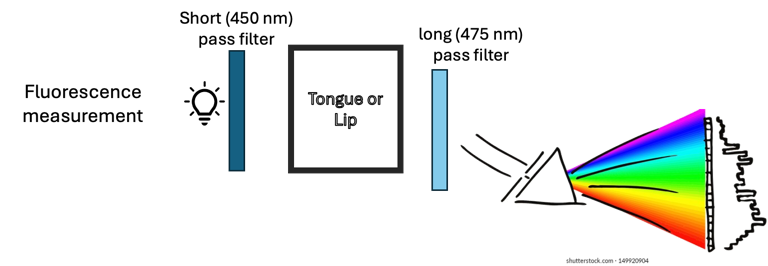

**Caption:** The six panels show the different measurement conditions.  The three columns show data acquired with each of three excitation lights (405 nm, 415 nm, 450nm).  The two rows show data acquired from the lip (top) and the tongue (bottom). The four curves in each panel show data from four different subjects, all measured with the same excitation light.  The curves are all normalized to match at 580 nm.  

Observations for the text:  

- The lip data are very similar from 500-700 nm

- In that regime we see small modulations at the oxyhemoglobin absorption bands of 540nm and 580nm

- The tongue data are very similar in the 500-600nm

- There are also small dips at the oxyhemoglobin bands (there, but harder to see)

- The tongue data vary between 600-700nm because of porphyrins and chlorophyll 

## Initialize ISET

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};

% Not normalized.
nWave = [];  % 580 
yScale = 'linear';
T = oeDatabaseCreate;

## Lip 405 (980 mA)

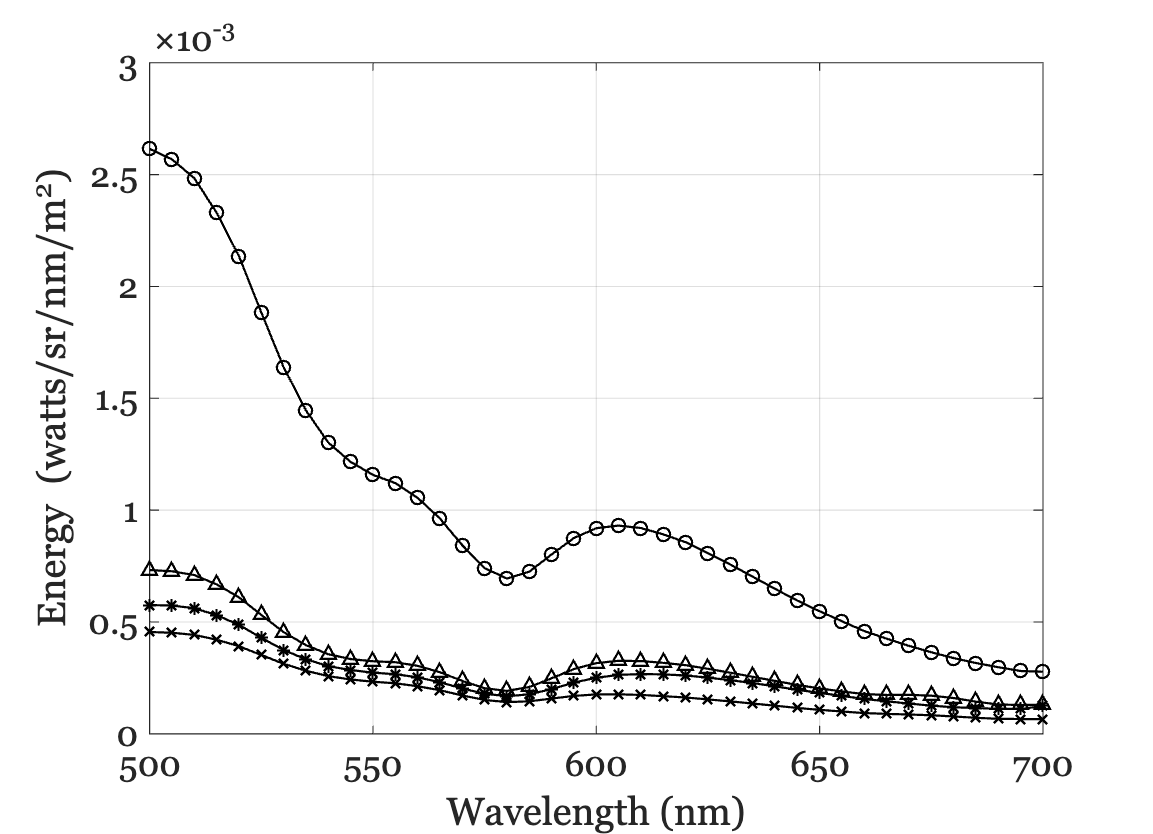

lipFiles405 = ieTableGet(T,'ewave',405,'substrate','lip','elevel',980,'return','files');
data = oeReadFiles(lipFiles405,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(lipFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

## Lip 415 (980 mA)

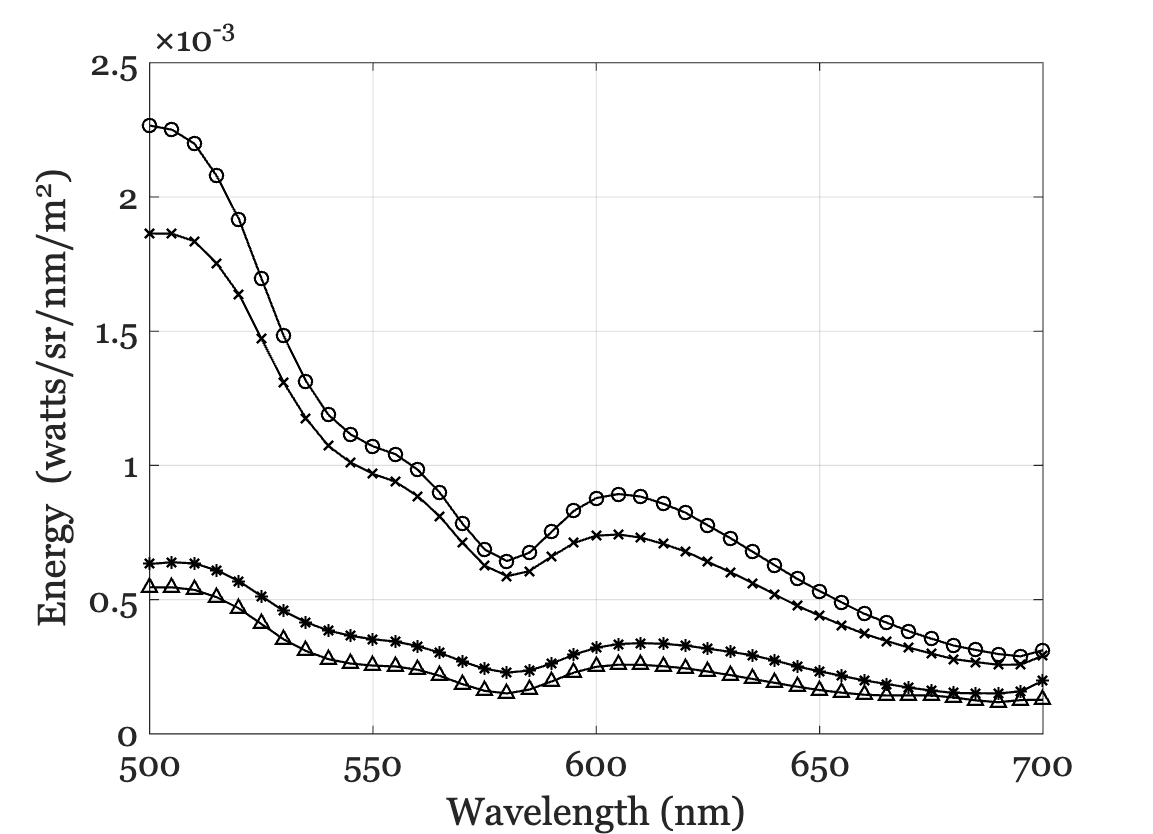

lipFiles415 = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910,'return','files');

% Collected on the same day as above.
selected = [11,12,13,14];
lipFiles415 = lipFiles415(selected);
data = oeReadFiles(lipFiles415,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(lipFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

## Lip 450 (870 mA)

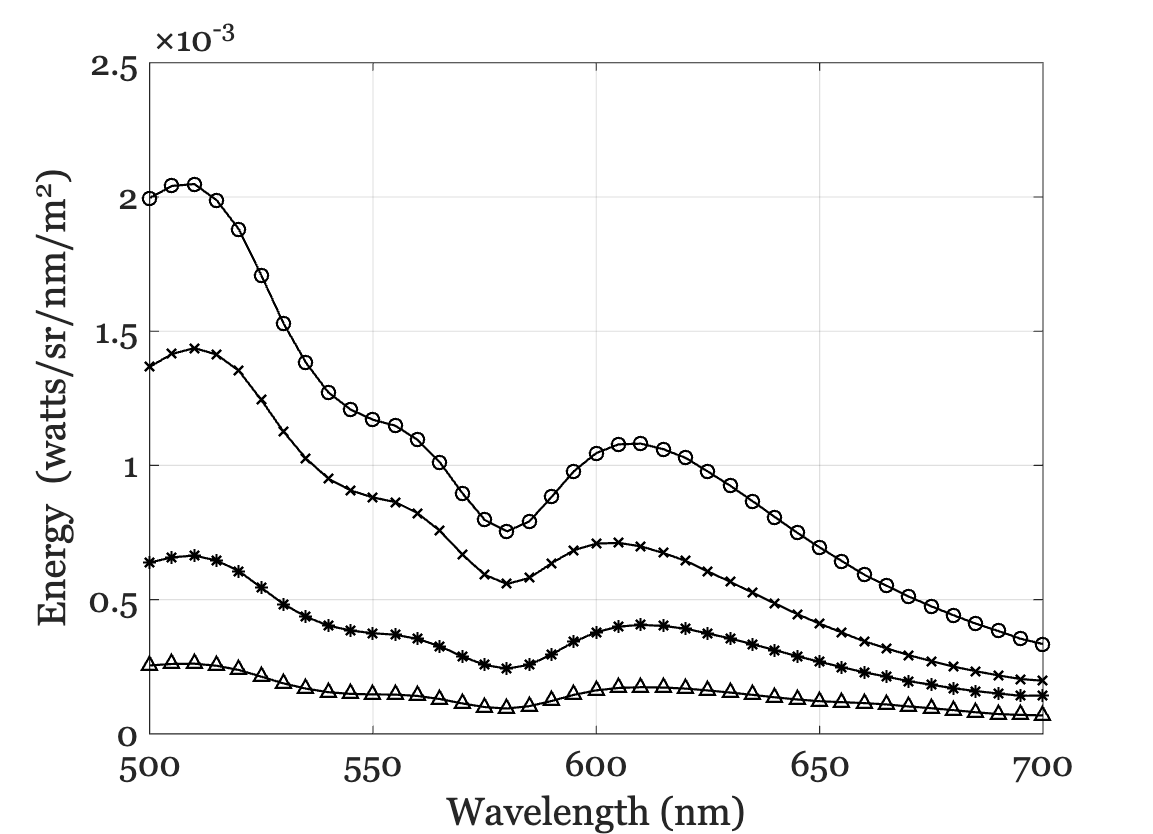

lipFiles450 = ieTableGet(T,'ewave',450,'substrate','lip','elevel',870,'return','files');

data = oeReadFiles(lipFiles450,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(lipFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

## Expected tongue radiance from pure reflectance

symbols = {'kx-','k*-','k^-','ko-'};
T2 = oeDatabaseLightsCreate;
unwanted405 = ieTableGet(T2,'condition','unwantedreflected','ewave',405,'elevel',980);
unwanted415 = ieTableGet(T2,'condition','unwantedreflected','ewave',415,'elevel',910);
unwanted450 = ieTableGet(T2,'condition','unwantedreflected','ewave',450,'elevel',870);

tongue = ieReadSpectra('tongue.mat',waves); 
meanTongueReflectance = mean(tongue,2);

data405 = oeReadFiles(unwanted405,'waves',waves);
predicted405= data405.*meanTongueReflectance;

data415 = oeReadFiles(unwanted415,'waves',waves);
predicted415 = data415.*meanTongueReflectance;

data450 = oeReadFiles(unwanted450,'waves',waves);
predicted450 = data450.*meanTongueReflectance;


## Tongue 405 (980 mA)

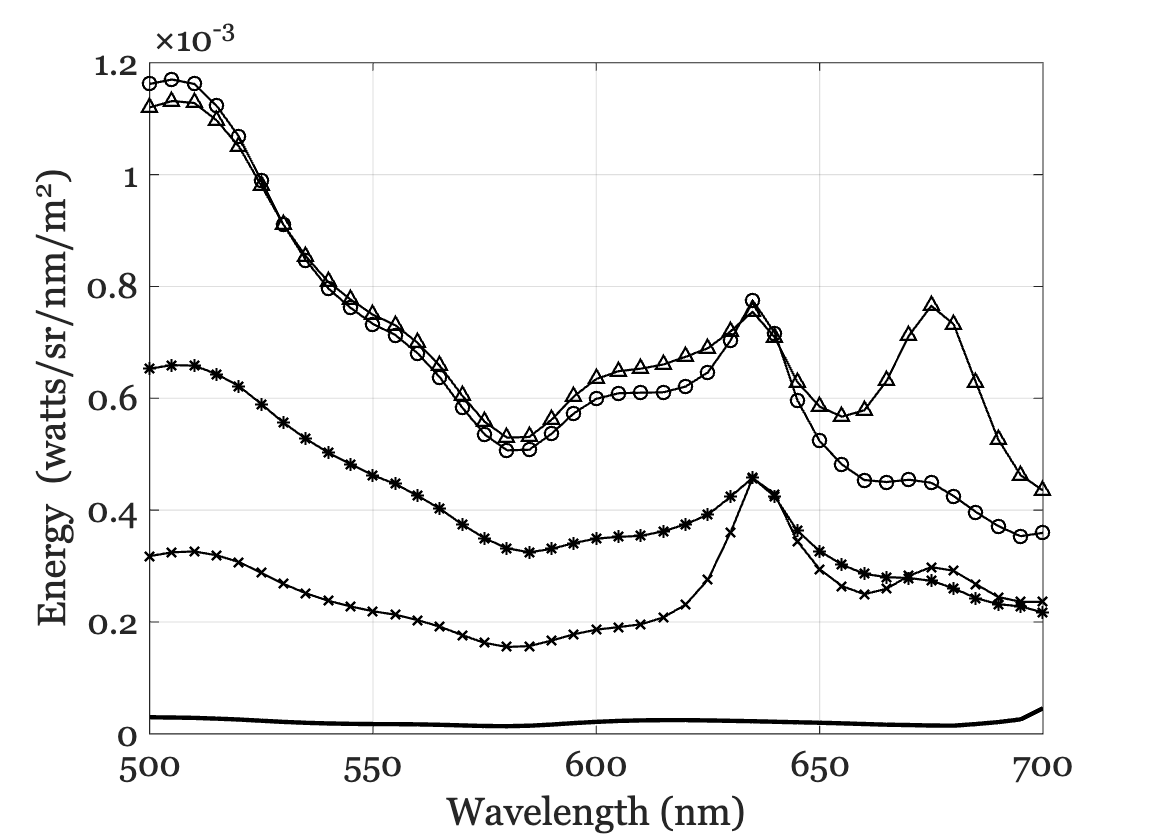

tongueFiles405 = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',980,'return','files');

% Collected on the same day as above.
selected = [1,2,4,5];
tongueFiles405 = tongueFiles405(selected);
data = oeReadFiles(tongueFiles405,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(tongueFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end
plot(waves,predicted405,'k','LineWidth',2);

grid on;
set(gca,'yscale',yScale);
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

disp(tongueFiles405);

    "spd-2024-03-12-11-405nm-J-tongue-980mA.mat"
    "spd-2024-03-14-Z-405nm_tongue_980mA-1.mat"
    "spd-2024-03-19-B_405nm_tongue_980mA.mat"
    "spd-2024-03-19-D_405nm_tongue_980mA.mat"



## Tongue 415 (980 mA)

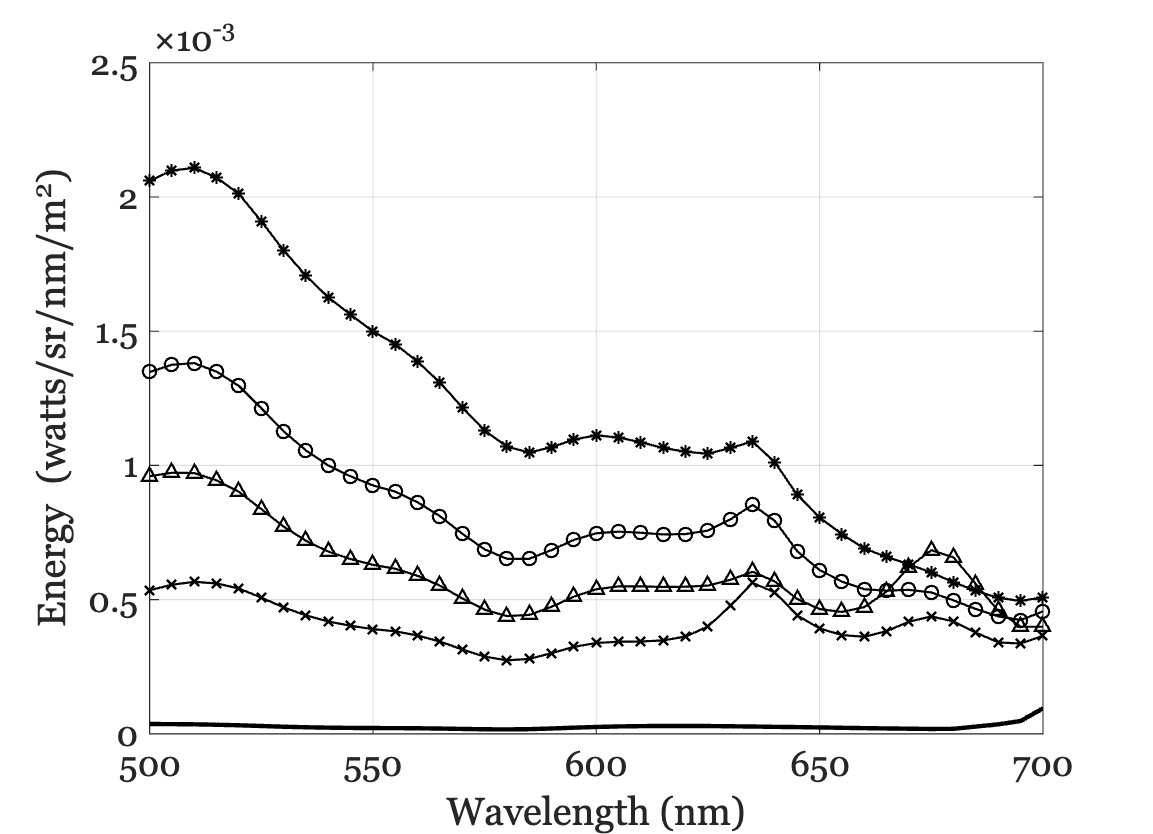

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files');

% Collected on the same day as above.  J,Z,B,D
selected = [11,12,13,14];
tongueFiles415 = tongueFiles415(selected);
data = oeReadFiles(tongueFiles415,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(tongueFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end
plot(waves,predicted415,'k','LineWidth',2);

set(gca,'yscale',yScale);
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

## Tongue 450 (870 mA)

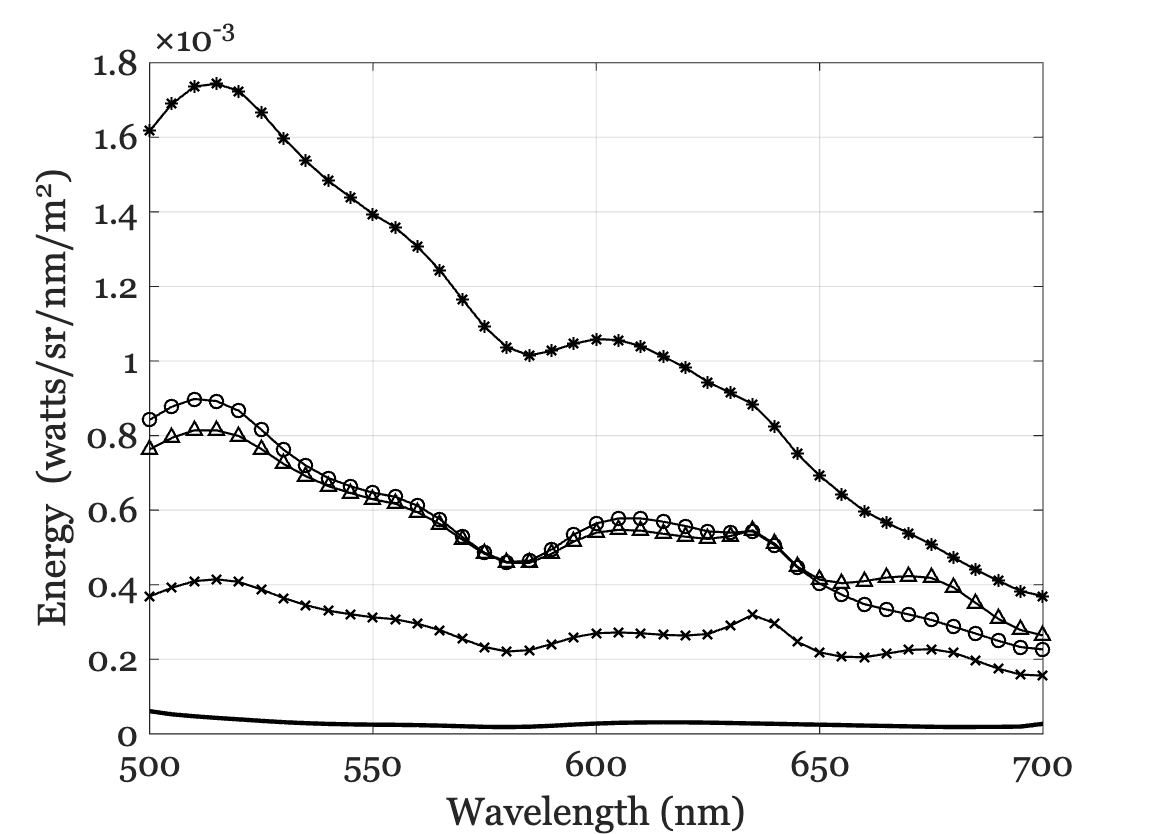

tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');

% We couldn't find J at 870 with 450 nm excitation.
tmp = ieTableGet(T,'ewave',450,...
    'substrate','tongue',...
    'elevel',460,...
    'subject','J',...
    'return','files');
tongueFiles450 = cat(1,tmp,tongueFiles450);
data = oeReadFiles(tongueFiles450,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(tongueFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end
plot(waves,predicted450,'k','LineWidth',2);

grid on;
set(gca,'yscale',yScale);
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end

fprintf('--------Current list of files-------\n');

--------Current list of files-------



disp(lipFiles405);

    "spd-2024-03-12-11-405nm-J-lip-980mA.mat"
    "spd-2024-03-14-Z-405nm_lip_980mA.mat"
    "spd-2024-03-19-B_405nm_lip_980mA.mat"
    "spd-2024-03-19-D_405nm_lip_980mA.mat"



disp(tongueFiles405);

    "spd-2024-03-12-11-405nm-J-tongue-980mA.mat"
    "spd-2024-03-14-Z-405nm_tongue_980mA-1.mat"
    "spd-2024-03-19-B_405nm_tongue_980mA.mat"
    "spd-2024-03-19-D_405nm_tongue_980mA.mat"




disp(lipFiles415);

    "spd-2024-03-12-11-415nm-J-lip-910mA.mat"
    "spd-2024-03-14-Z-415nm_lip_910mA.mat"
    "spd-2024-03-19-B_415nm_lip_910mA.mat"
    "spd-2024-03-19-D_415nm_lip_910mA.mat"



disp(tongueFiles415);

    "spd-2024-03-12-11-415nm-J-tongue-910mA.mat"
    "spd-2024-03-14-Z-415nm_Tongue_910mA.mat"
    "spd-2024-03-19-B_415nm_tongue_910mA.mat"
    "spd-2024-03-19-D_415nm_tongue_910mA.mat"




disp(lipFiles450);

    "spd-2024-03-12-11-450nm-J-lip-870mA.mat"
    "spd-2024-03-14-Z-450nm_lip_870mA.mat"
    "spd-2024-03-19-B_450nm_lip_870mA.mat"
    "spd-2024-03-19-D_450nm_lip_870mA.mat"



disp(tongueFiles450);

    "spd-2024-03-12-450nm-J-tongue-460mA-1.mat"
    "spd-2024-03-14-Z-450nm_tongue_870mA.mat"
    "spd-2024-03-19-B_450nm_tongue_870mA.mat"
    "spd-2024-03-19-D_450nm_tongue_870mA.mat"

